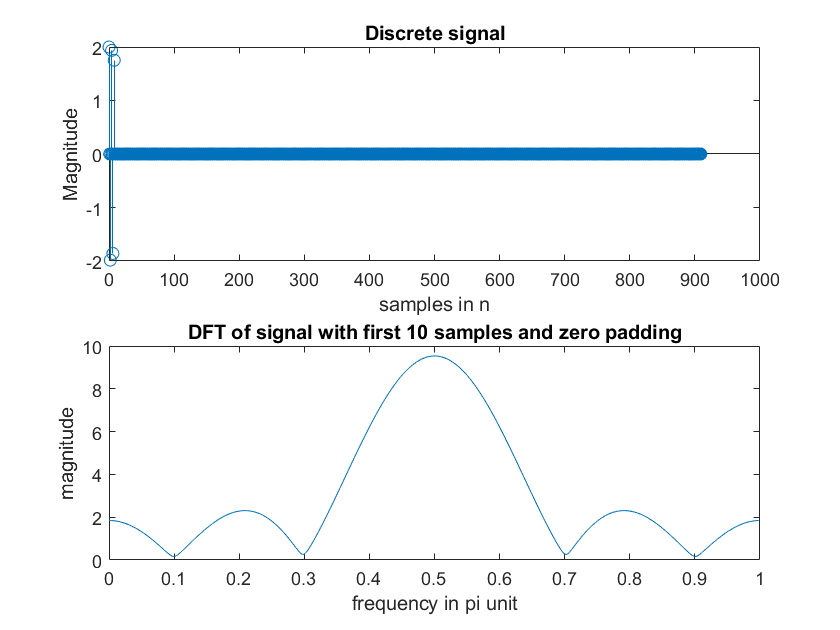

% to get a smoother version of the spectrum, used zero padding operation 
n=0:9;
x=[cos(0.52*pi*n)+cos(pi*0.48*n) zeros(1,900)];
n=0:length(x)-1;
X=dfs(x,length(n));
figure('Name','Zeropadding')
subplot(2,1,1)
stem(n,x)
title('Discrete signal')
xlabel('samples in n')
ylabel('Magnitude')
k=0:1:length(n)/2-1;
w=2*pi*k/length(n);
subplot(2,1,2)
X=abs(X(1:length(X)/2));
plot(w/pi,X)
title('DFT of signal with first 10 samples and zero padding')
xlabel('frequency in pi unit')
ylabel('magnitude')

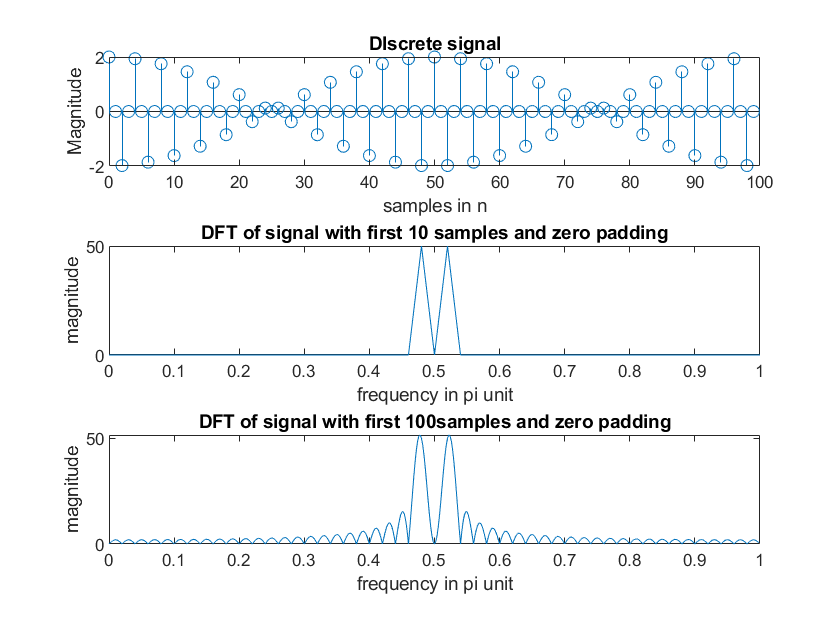

% cooment
% Get smoother version
% But don't get exact spectrum information since in plot the sequence has
% dominant frequency is w=0.5hz. 
% but the sequence has two frequncies w=0.48hz and w=0.52hz

% Take more samples to get better spectral information
n=0:99;
x=cos(0.52*pi*n)+cos(pi*0.48*n);
X=dfs(x,length(n));
f2=figure('Name','First 100 samples');
subplot(3,1,1);
stem(n,x);
title('DIscrete signal')
xlabel('samples in n')
ylabel('Magnitude')
k=0:1:length(n)/2;
w=2*pi*k/length(n);
subplot(3,1,2)
X=abs(X(1:length(X)/2+1));
plot(w/pi,X)
title('DFT of signal with first 10 samples and zero padding')
xlabel('frequency in pi unit')
ylabel('magnitude')

n=0:99;
x=[cos(0.52*pi*n)+cos(pi*0.48*n) zeros(1,900)];
n=0:length(x)-1;
X=dfs(x,length(n));
% figure('Name','Zeropadding')
k=0:1:length(n)/2-1;
w=2*pi*k/length(n);
subplot(3,1,3)
X=abs(X(1:length(X)/2));
plot(w/pi,X)
title('DFT of signal with first 100samples and zero padding')
xlabel('frequency in pi unit')
ylabel('magnitude')